### Ładowanie pliku obrazu

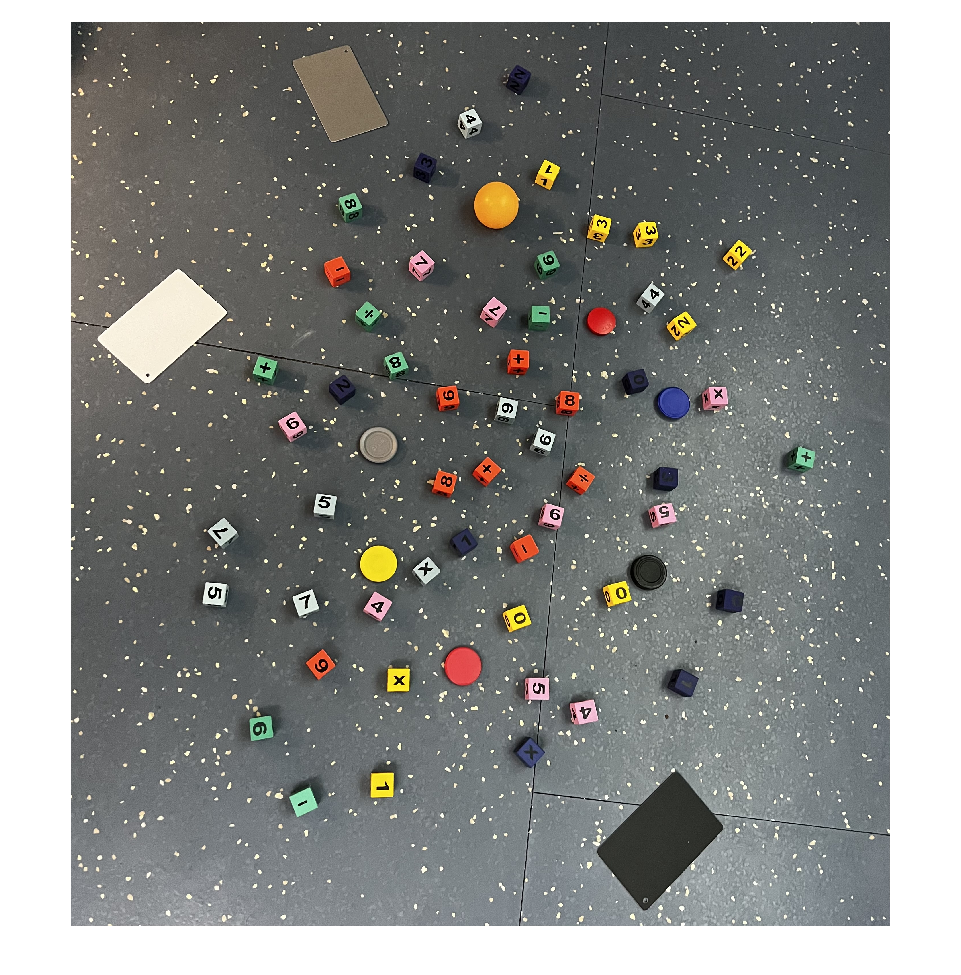

RGB = imread('sample.jpg');
imshow(RGB);

### Separacja kanału barwy

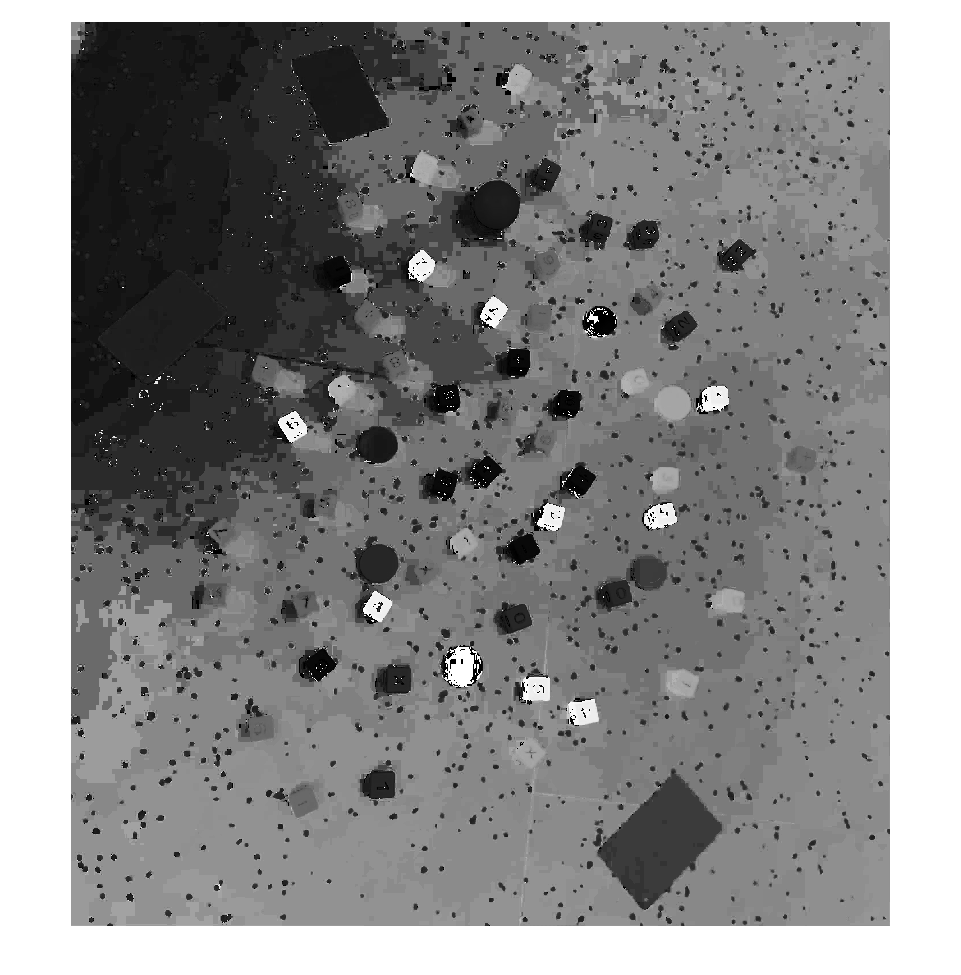

HSV = rgb2hsv(RGB);
H = HSV(:,:,1);
imshow(H);

### Wizualizacja kanału barwy

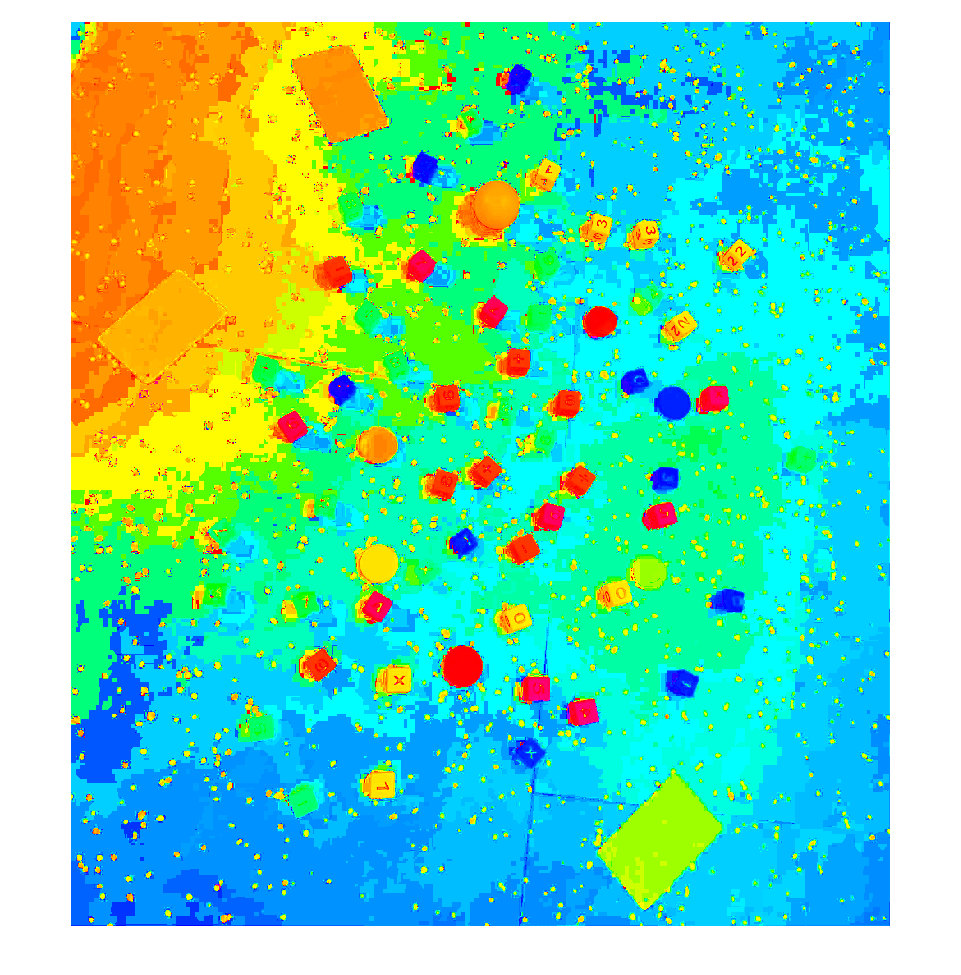

imshow(H);
colormap('hsv');

### Progowanie kolorów

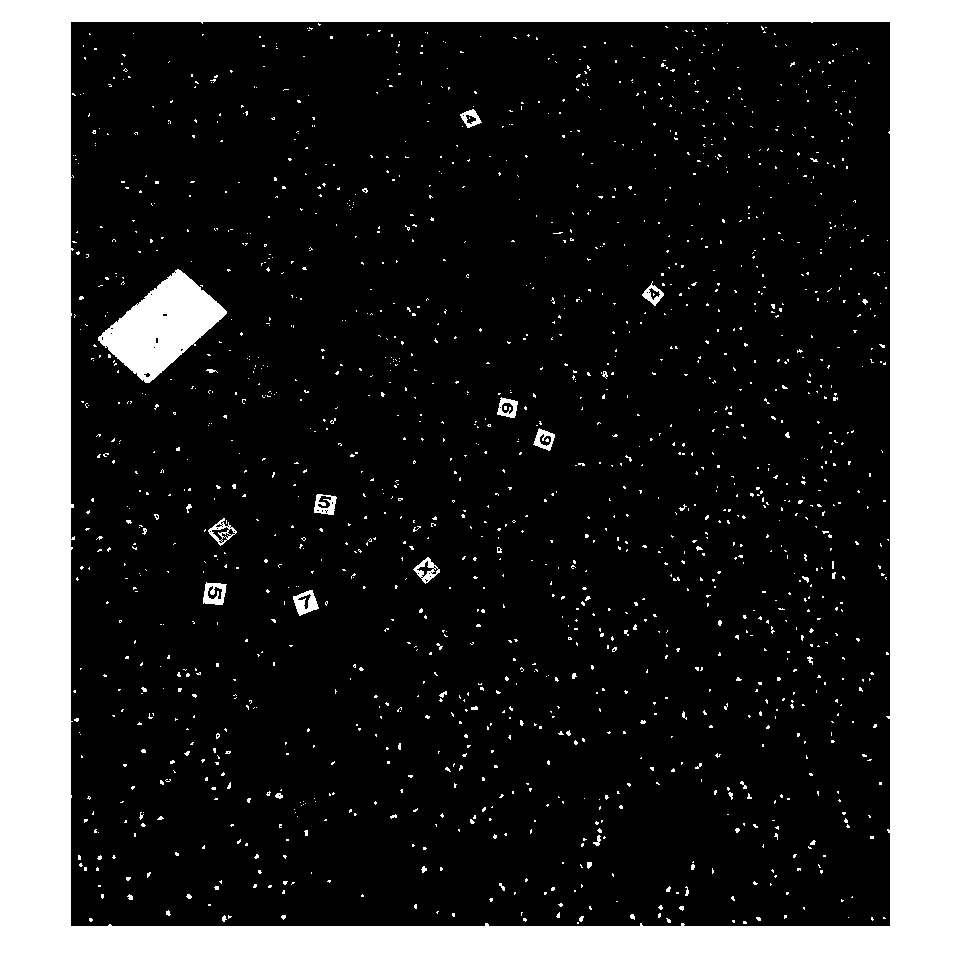

thresholds = dictionary( ...
    "red", {[0.992, 0.071; 0.375, 1.000; 0.725, 1.000]}, ...
    "yellow", {[0.144, 0.233; 0.442, 1.000; 0.872, 1.000]}, ...
    "green", {[0.205, 0.433; 0.165, 1.000; 0.235, 1.000]}, ...
    "blue", {[0.519, 0.730; 0.222, 0.785; 0.126, 0.717]}, ...
    "magenta", {[0.828, 0.968; 0.000, 0.696; 0.587, 1.000]}, ...
    "orange", {[0.086, 0.118; 0.744, 0.878; 0.876, 1.000]}, ...
    ... % "gray", {[0.808, 0.793; 0.170, 0.326; 0.426, 0.676]}, ...
    ... % "black", {[0.970, 0.605; 0.000, 0.155; 0.000, 0.219]}, ...
    "white", {[0.105, 0.517; 0.000, 0.233; 0.832, 1.000]} ...
);

colors = keys(thresholds);


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Create mask based on chosen histogram thresholds
masks = dictionary();
for color_index = 1:length(colors)
    color = colors(color_index);
    value = thresholds(color);
    value = value{1};
    channel1Min = value(1, 1);
    channel1Max = value(1, 2);
    channel2Min = value(2, 1);
    channel2Max = value(2, 2);
    channel3Min = value(3, 1);
    channel3Max = value(3, 2);
    if (channel1Min <= channel1Max)
    mask = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
    masks(color) = {mask};
    else 
    mask = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
    masks(color) = {mask};
    end
end

imshow(mask);

### Poprawa maski

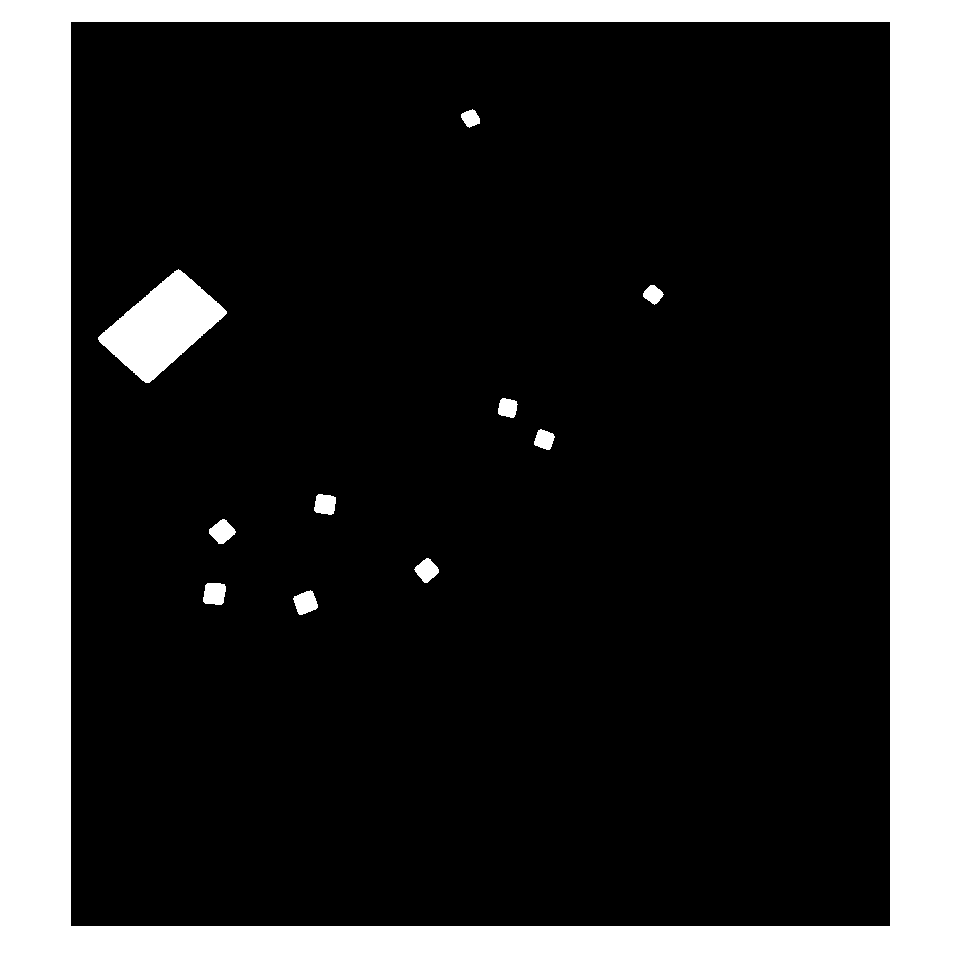

for color_index = 1:length(colors)
    color = colors(color_index);
    BW = masks(color);
    BW = BW{1};

    % Close mask
    radius = 3;
    decomposition = 0;
    se = strel('disk', radius, decomposition);
    BW = imclose(BW, se);
    
    % Fill holes
    BW = imfill(BW, 'holes');

    % Open mask
    radius = 11;
    decomposition = 0;
    se = strel('disk', radius, decomposition);
    BW = imopen(BW, se);

    masks(color) = {BW};
    imshow(BW);
end

### Filtracja regionów po rozmiarze i odczytanie średniej barwy

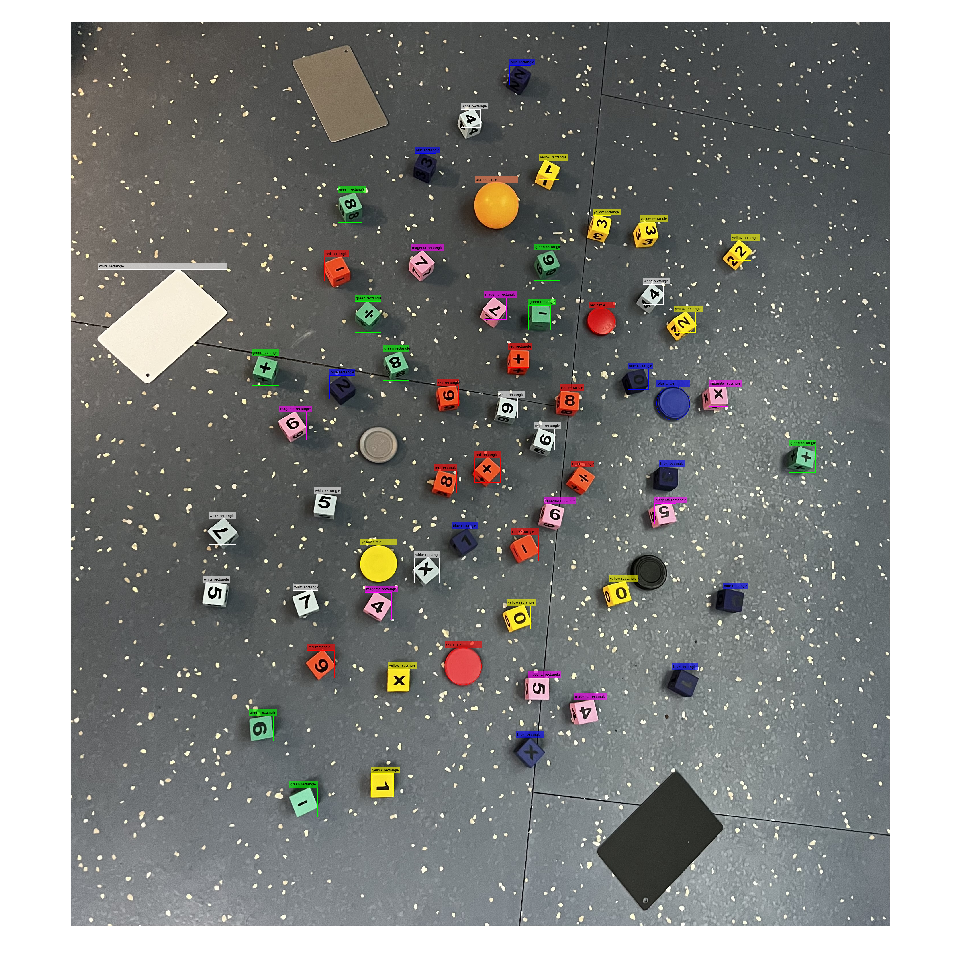

out = RGB;
for color_index = 1:length(colors)
    colorname = colors(color_index);
    BW = masks(colorname);
    BW = BW{1};
    props = regionprops(BW, {'Area', 'Eccentricity', 'EquivDiameter', 'BoundingBox', 'PixelIdxList', 'Centroid', 'Circularity'});
    for i=1:size(props, 1)
        if props(i).Area > 500
            % avg_h = mean(H(props(i).PixelIdxList));
            % color_avg = hsv2rgb([avg_h, 1, 1]) * 255;
            if strcmp(colorname, 'orange')
                color = [255 127 80];
            elseif strcmp(colorname, 'gray')
                color = [150 150 150];
            else
                color = validatecolor(colorname) * 255;
            end

            if props(i).Circularity > 0.92
                shape = "circle";
                pos = [props(i).Centroid, props(i).EquivDiameter/2];
            else
                shape = "rectangle";
                pos = props(i).BoundingBox;
            end
            % label = sprintf("%.3f", avg_h);
            label = sprintf("%s %s", colorname, shape);
            out = insertObjectAnnotation(out, shape, pos, label, "Color", color) ;
        end
    end
end
imwrite(out, "output.png");
imshow(out);